# **Project 3**

# (Please press Run all sections(F5) to check my code)

**Background**

In this project, we need to use matlab to deal with a data file (*Bananas.csv) *with almost 12000 entries. There are 4 column variables Origin, Date, Price and Units. Moreover the unit of prices is pound per kilogram of bananas and the ‘all bananas’ in Origin column is an average of the collective data for that date.

**Q1**

In this question, we need to produce a list which contains different entries in the Origin column.

**Implementation**

First, I use *readtable() to *read *bananas-18jan21.csv *as table and named it as *dat.*

In order to better process the data a bit later. I preprocess the data which is just simply sorting the rows according to the Date. The function to do that is *sortrows().*

After that I apply function *unique() *to the Origin column in order to extract all different entries and no repetition. Finally using *transpose()* and *cell2table() *to make sure the output is a table with one row.

The following table shows the first 7 entries in my 1*27 table:


dat = readtable("bananas-18jan21.csv");%read data in matlab
dat = sortrows(dat,"Date","descend");%sorting the rows according to the Date
Origin = transpose(unique(dat.Origin));%Find all the different elements under Origin
cell2table(Origin)%convert the cell into table

ans = 1×27 table
        Origin1            Origin2         Origin3       Origin4        Origin5         Origin6          Origin7             Origin8                 Origin9             Origin10         Origin11       Origin12        Origin13         Origin14         Origin15         Origin16         Origin17        Origin18         Origin19        Origin20       Origin21        Origin22      Origin23         Origin24        Origin25        Origin26            Origin27     
    _______________    ______________

`The following are the all `distinct entries under the Origin header:

`'acp_bananas'    'all_bananas'    'belize'     'brazil'     'cameroon'    'colombia'    'costa_rica'    'dollar_bananas'    'dominican_republic'    'ecuador'    'eu_bananas'    'ghana'      'guadeloupe'    'guatemala'    'honduras'    'ivory_coast'    'jamaica'    'malaysia'    'martinique'    'mexico'     'nicaragua'    'panama'     'somalia'    'st_vincent'    'surinam'    'venezuela'    'windward_isles'`

**Q2**

In this question, we want to find out which three countries the average price were lowest over the last 5 years of the data for that country, and for which three countries the average price were highest over the last 5 years of data for that country .The '5 years of the data for that country' means that if the last date entry for a country is say 05-14-2000 then the valid data is from 05-14-1995 to 05-14-2000.

**Implementation**

First, due to ‘all bananas’ in Origin is not a country, so we need to remove that. From last question, It is clear from the list that the index of ‘all bananas’ is 2.So we can remove the second entry of *Origin.*

I write a *for *loop to calculate the average price of bananas in each country in the last five years. Inside the *for *loop, I use *find() *to find all the corresponding index in the table about a origin.

After that I extract the specific rows according to the big table *dat *and named it as* temp*. Since *dat* has been sorted by date. So we can just easily find the earliest valid data by subtracting 5 years from the first entry of *temp{1,"Date"}*.

Finally finding the average prices for valid date and creating a table *t* which has two column, 'Origin' and 'average' and sort *t *by 'average'.

Origin(2) = [];%remove the 'all bananas'all bananas’
average = [];%create a vector to collect the average prices for each orign
for o = Origin
Inx = find(contains(getfield(dat,'Origin'),o{1}));
temp = dat(Inx,:);
valid = find(temp{:,"Date"} >= temp{1,"Date"}-calyears(5),1,"last");
average = [average;sum(temp{1:valid,"Price"})/valid];
end
Origin = Origin';
t = table(Origin,average);
t =sortrows(t,2);
t(1:3,:)%print the first 3 rows of the table

ans = 3×2 table
          Origin          average
    __________________    _______

    {'windward_isles'}    0.47026
    {'surinam'       }    0.50714
    {'venezuela'     }    0.52268


Windward isles,Surinam and Venezuela had the lowest average price over the last 5 years.

Windward isles ranked first,Surinam second and Venezuela third.

t(end:-1:end-2,:)%print the last 3 rows of the table in reverse order

ans = 3×2 table
        Origin        average
    ______________    _______

    {'somalia'   }       0.83
    {'panama'    }    0.78896
    {'costa_rica'}    0.76873


Somalia, Panama and Costa rica three had the highest average price over the last 5 years.

Somalia ranked first, Panama second, and Costa third.

Q3

In this question,we need to plot the variation of the prices of bananas with countries of origin‘costa rica’, ‘windward isles’ and ‘ecuador’ as well as ‘all bananas’ in a same graph and comparing the prices.

**Implementation**

First,creating a cell *origin *has 4 elements namely ‘costa rica’, ‘windward isles’ and ‘ecuador’ as well as ‘all bananas’.

Second, creating *D *and* P *in order to collect the dates and prices for each of the 4 elements in *orign.*

After that,writing a for loop to plot *Date vs Price* for the 4 elements in *origin.*We can use a method similar to Q2 to extract specific data of different elements in origin from* dat *by using the function* find().*

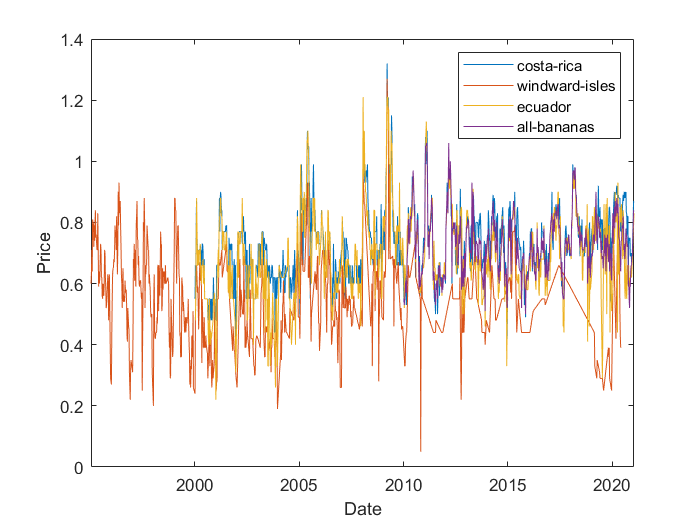

oirign = {'costa_rica', 'windward_isles','ecuador','all_bananas'};
D = {};P = {};i = 0;
for o = oirign
    i = i+1;
    %extract the index for o in dat
    Inx = find(contains(getfield(dat,'Origin'),o{1}));
    temp = dat(Inx,:);
    %make sure the order of elements in D is correspond to orign
    D{i} = temp.Date;
    %make sure the order of elements in P is correspond to orign
    P{i} = temp.Price;
    plot(D{i},P{i})
    hold on
end
hold off
legend({'costa-rica', 'windward-isles','ecuador','all-bananas'});
ylabel('Price')
xlabel('Date')

**Comment**

1.The prices of bananas are not stable as time evolution.

2.Costa Rica's prices volatility are relatively small.

3.The prices for windward isles are lower than others.

Q4

This question is similar to Q3,But we only need to consider the time period from 2016-01- 01 to 2020-12-31 and further more comment on any seasonal trends.

**Implementation for plotting**

Creating *D1 *and* P1 *in order to collect the dates and prices for each of the 4 elements in *origin *between 2016-01- 01 to 2020-12-31*.*So the elements in *D1 *and* P1 *are subsets of the elements is *D* and *P*. So we can use function *find() *to find the valid index in *D* and *P *to generate *D1 *and* P1.*Because *dat* is arranged in chronological order, so we can find just find the index of upper bound of the valid date *upper *and *lower *for lower bound. The index between *upper *and *lower *are all valid data. 

Finally, we can also use *length() *to find how many valid data for a given element in *origin.*

D1 = {};P1 = {};
for k = 1:4
    tempD = D{k};tempP = P{k};
    %finding the index of upper bound of the valid date
    upper = find(D{k} <= datetime(2020,12,31),1,"first");
    %finding the index of lower bound of the valid date
    lower = find(D{k}>= datetime(2016,01,01),1,"last");
    D1{k} = tempD(upper:lower);
    P1{k} = tempP(upper:lower);
    plot(tempD(upper:lower),tempP(upper:lower))
    %print the number of available data in a orign
    fprintf('The number of valid data for %s is %s',oirign{k},num2str(length(D1{k})));
    hold on    
end

The number of valid data for costa_rica is 251

The number of valid data for windward_isles is 32

The number of valid data for ecuador is 224

The number of valid data for all_bananas is 251

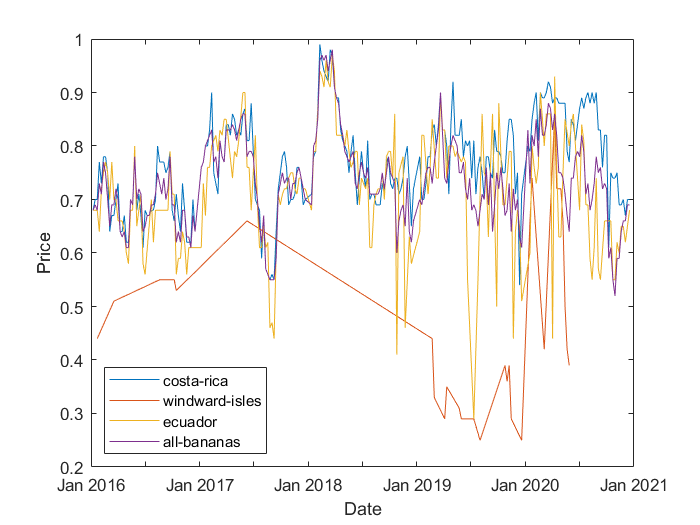

hold off
legend({'costa-rica', 'windward-isles','ecuador','all-bananas'},'Location','southwest');
ylabel('Price')
xlabel('Date')

After plotting the data, we need to consider if there is any seasonal trends.

**Formulate the problem mathematically**

First we can consider the prices as discrete signals. We can try to use discrete Fourier transform to the data. In matlab, we can use the `fft()` to the data. However, this needs the time between adjacent data points is equal, so we need to check that first.

We can use *for *loop to check the data for 'costa-rica', 'windward-isles','ecuador' and 'all-bananas' and using *datenum() *to convert the datetime variable into integers. After that we find all the difference between two adjacent time and find out if all the difference is the same.

check = [];
for k=1:4
    D1{k};
    l = datenum(D1{k});%convert the datetime into a number
    %check the time between adjacent data points is equal or not
    check = [check length(unique(l(2:length(l))-l(1:length(l)-1)))==1];
end
check

check =      0     0     0     0


According to the output,the time between adjacent data points for the 4 data sets all are not equally spaced.

**A useful numerical method**

**Linear interpolation** on a set of data points (*x*0, *y*0), (*x*1, *y*1), …, (*x*n, *y*n) is defined as the concatenation of linear interpolants between each pair of data points.[1] 

So we can use linear interpolation[1] to the data and generating all integer points between the two end points of the given time period.

**Remark**:the points are all equally spaced,since the time different $\textrm{dt}=1$,In other words, the new data set describes the price of each day in a given period of time.

After that,we can use *fft() *to the news data sets,and named it as *z* and remove the first element of *z.*

In the frequency space of Fourier transform $\textrm{Fs}=1/\textrm{ds}=1$*.*So the maximum frequency is $1/2$*.*

We can consider a half of the data.Since $\textrm{Power}={\textrm{Re}\left(z\right)}^2 +{\textrm{Im}\left(z\right)}^2 ={\left|z\right|}^2$,In matlab we can just using *abs(z)^2.*

Since $\textrm{period}=1/\textrm{frequency}$,we can plot the *period vs Power.*(period is measured in days per cycle.)

Finally, we can determine how many days it takes for prices to repeat similar patterns by finding out the days have maximum power.

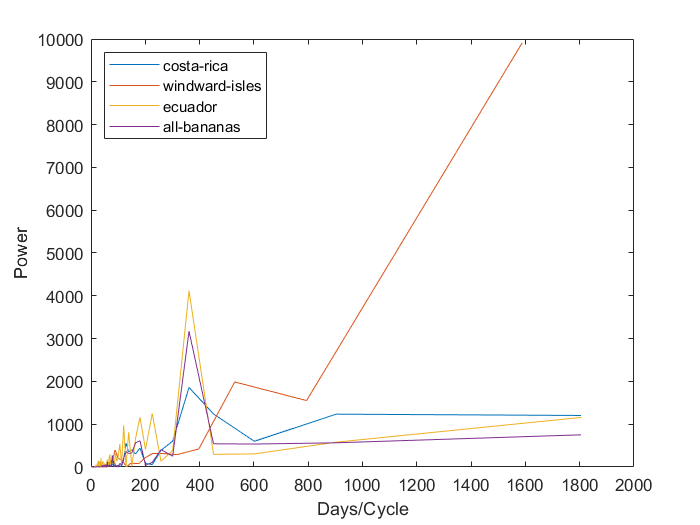

Cycle = [];%creating a empty vector to collect the days have maximum power
for k = 1:4
    l = datenum(D1{k});%convert the datetime into a number
    x = l(end):l(1);%generate the time interval
    %generate the prices for all day in x using linear interpolation
    y = interp1(l,P1{k},x,'linear'); 
    z = fft(y);%using fast Fourier transform
    z(1) = [];%remove the first element in z
    n = length(z);%find the number of data points
    power = abs(z(1:floor(n/2))).^2;%find the power spectrum of half data points
    maxfreq = 1/2;                  
    freq = (1:n/2)/(n/2)*maxfreq;%find the frequency range
    period = 1./freq;%find the period range
    plot(period,power)%plot period vs Power
    xlabel('Days/Cycle')
    ylabel('Power')
    [M, I]= max(power);%find the index of power have maximum value
    Cycle = [Cycle period(I)];   
    hold on
end
legend({'costa-rica', 'windward-isles','ecuador','all-bananas'},'Location','northwest');

Cycle = Cycle';
oirign = oirign';
%creating a 4*2 table,the first column is the 4 different data sets
%the second column is the corresponding days for a cycle
table(oirign,Cycle)

ans = 4×2 table
          oirign          Cycle
    __________________    _____

    {'costa_rica'    }     361 
    {'windward_isles'}    1588 
    {'ecuador'       }     361 
    {'all_bananas'   }     361 


**Comment**

From the graphs and the table, we can find out that there is cycle repeating every 361 days for 'costa-rica','ecuador' and 'all-bananas', which means the prices of banana fluctuates nearly with annual period.

However, we can’t comment the same like previously for 'windward-isles' .The reason is that we can infer from the first plot in Q4. There is not sufficient data points provided or just checking the number of data points in 'windward-isles' which is just 32, thus using Interpolating method to estimate the whole curve is not accurate. We can’t comment any trend in 'windward-isles'.

**Reference**


$$\left\lbrack 1\right\rbrack \textrm{wikipedia},\textrm{Linear}\;\textrm{interpolation},\textrm{last}\;\textrm{edited}\;\textrm{on}\;14\;\textrm{April}\;2021$$
